# Modelo de calidad 

close all; clc; clearvars;

Etiqueta de calidad con 5 categorías: 

- 0 - Imagen no revisada (se asume correcta, pero podría tener problemas de calidad) 

- 1 - Bajo contraste 

- 2 - Desenfoque 

- 3 - Ruido 

- 4 - Calidad correcta

## Caracteristicas calidad

- Extracción de caracteristicas

- Algoritmo de clasificación para las características extraídas

T_metadata = readtable('metadata.csv');

T_revisada = T_metadata;
T_revisada(T_revisada.quality == 0, :) = []; % eliminar las fotos no revisadas

### **Distribución categorias**

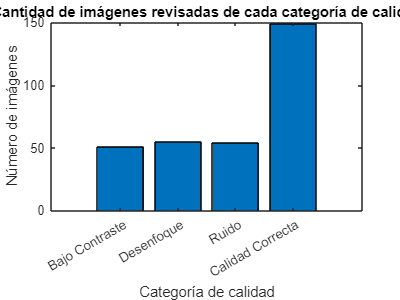

% analisis exploratorio (EDA)
num_bajocontraste = sum(T_revisada.quality == 1);
num_desenfoque = sum(T_revisada.quality == 2);
num_ruido = sum(T_revisada.quality == 3);
num_calidadcorrecta = sum(T_revisada.quality == 4);

figure('Position', [0 0 400 300]);
num_imagenes_revisadas = [num_bajocontraste, num_desenfoque, num_ruido, num_calidadcorrecta];
bar(1:4, num_imagenes_revisadas); title('Cantidad de imágenes revisadas de cada categoría de calidad');
xlabel('Categoría de calidad');
ylabel('Número de imágenes');
set(gca, 'XTick', 1:4, 'XTickLabel', {'Bajo Contraste', 'Desenfoque', 'Ruido', 'Calidad Correcta'});

Aunque las etiquetas en el conjunto de datos no están balanceadas, se ha decidido no aplicar técnicas de balanceo, ya que, en este caso particular, la falta de balanceo no tiene un impacto negativo significativo en el rendimiento del modelo. Para asegurar que la evaluación del modelo sea valida, se utilizan métricas de rendimiento que no se ven afectadas por el desequilibrio en las etiquetas, como la precisión balanceada.

### Extraer caracteristicas 

Extracción de las caractersticas de las imagenes revisadas, que se utilizara para entrenar el modelo.

% [n, m] = size(T_revisada);
% 
% entropia = zeros(n,1);
% min_intensidad= zeros(n, 1);
% max_intensidad= zeros(n, 1);
% rango_dinamico= zeros(n, 1);
% std_intensidad= zeros(n, 1);
% var_intensidad= zeros(n, 1);
% nitidez_borde = zeros(n, 1);
% score = zeros(n, 1);
% mse = zeros(n, 1);
% magnitud_transformada_promedio = zeros(n, 1);
% snr = zerons(n,1);
% filtro_laplace=[1, 1, 1; 1, -8, 1; 1, 1, 1];
% 
% for i = 1:n
%     I = imread(T_revisada.image{i});
%     entropia(i) = entropy(I);
% 
%     I = double(rgb2gray(I)); % damos por hecho que la imagen es de color (igual hacer un for para diferenciar)
% 
%     min_intensidad(i)=min(I(:));
%     max_intensidad(i)=max(I(:));
%     rango_dinamico(i)=max(I(:))-min(I(:));
%     std_intensidad(i) = std2(I(:)); % desviación estandar
%     var_intensidad(i) =var(I(:)); % varianza
% 
%     I2=imfilter(I, filtro_laplace);
%     nitidez_borde(i) = sum(abs(I2(:)));
% 
%     I_filtrada=medfilt2(I);
%     mse(i)=immse(I_filtrada, I); %Cuanto menor sea el valor del MSE, menor será la diferencia entre las dos imágenes, lo que indica una mejor calidad de la imagen.
%     snr(i)=psnr(I_filtrada, I); 
%     score(i) = brisque(I);
% 
%     transformada = fft2(I);
%     magnitud_transformada = abs(transformada);
%     magnitud_transformada_promedio(i) = mean(magnitud_transformada(:));
% end
% 
% T_caracteristicas = table(T_revisada.quality, entropia, min_intensidad, max_intensidad, rango_dinamico, std_intensidad, var_intensidad, nitidez_borde, mse, snr, score, magnitud_transformada_promedio, 'VariableNames', {'quality', 'entropia', 'min_intensidad', 'max_intensidad', 'rango_dinamico', 'std_intensidad', 'var_intensidad', 'nitidez_borde', 'mse', 'snr', 'score', 'magnitud_transformada_promedio'});
% T_caracteristicas.imagen = T_revisada.image;

% writetable(T_caracteristicas, 'CaracteristicasCalidadREVISADAS_TODAS.csv');

## Desarrollo modelo

### Cargar las caracteristicas extraidas

T = readtable("CaracteristicasCalidadREVISADAS.csv");

#### Correlación

T.mse_gauss = [];
T.snr_gauss = [];

variables=T.Properties.VariableNames

variables = 1×12 cell array
    {'quality'}    {'entropia'}    {'min_intensidad'}    {'max_intensidad'}    {'rango_dinamico'}    {'std_intensidad'}    {'var_intensidad'}    {'nitidez_borde'}    {'mse_mediana'}    {'snr_mediana'}    {'energia'}    {'imagen'}


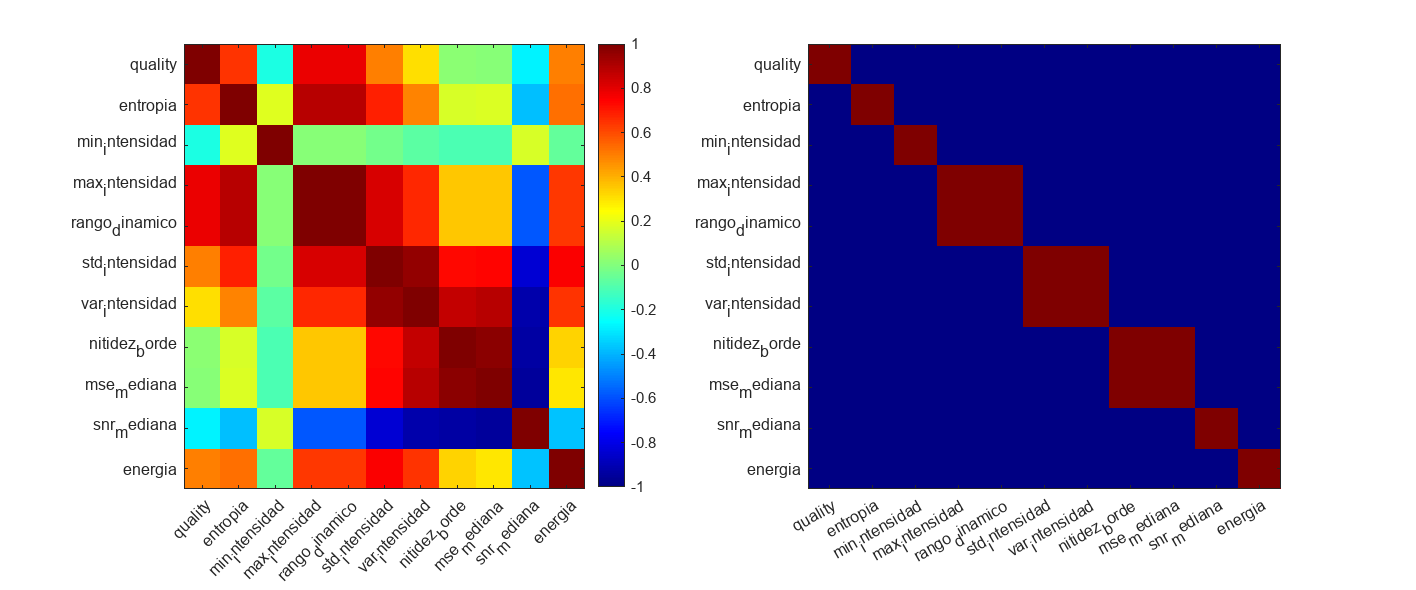

X = T{:, 1:end-1};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure('Position', [0 0 2400 1000]); subplot(1,2,1); imagesc(R); clim([-1 1]);
xticks(1:30); xticklabels(variables(:));
yticks(1:30); yticklabels(variables(:));
colormap(jet); colorbar;
subplot(1,2,2); imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:30); xticklabels(variables(:));
yticks(1:30); yticklabels(variables(:));

#### Preprocesamiento

T.imagen=[];
T.min_intensidad = [];
T.max_intensidad = [];
T.std_intensidad = [];
T.nitidez_borde = [];
T.energia = [];

Las caracteristicas finales que se usaran para desarrollar el modelo de la clasificación de calidad son: entropia, rango dinamico, varianza, snr y mse (despues del filtro de mediana)

[n, ~]=size(T);
T.quality = cellstr(num2str(T.quality)); %convertir quality en variable categorica
for i = 1:n
    if T.quality{i} == '1'
        T.quality{i} = 'Bajo Contraste';
    elseif T.quality{i} == '2'
        T.quality{i} = 'Desenfoque';
    elseif T.quality{i} == '3'
        T.quality{i} = 'Ruido';
    elseif T.quality{i} == '4'
        T.quality{i} = 'Calidad Correcta';
    end
end

### Divisón de datos

rng(4); 
p = 0.2;
cv_out = cvpartition(T.quality, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.quality, 'KFold', k, 'Stratify', true);

### **Entrenamiento de los modelos**

results = table;

#### **K-nearest neighbors (KNN)**

mdl_knn = fitcknn(T_train, 'quality', 'NumNeighbors', 3, 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_knn); 

Y_pred = kfoldPredict(mdl_knn);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

Y_test  = T.quality(cv_out.training);
confMat = confusionmat(Y_test, Y_pred);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy);

figure('Position', [0 0 2800 750]); subplot(2,3,1); confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - KNN');

results = [results; table("knn", mdl_loss, accuracy, Balanced_Accuracy, 'VariableNames',{'model','loss','accuracy', 'balanced accuracy'})];

#### **Classification Trees**

mdl_tree = fitctree(T_train, 'quality', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);
accuracy = sum(strcmp(T_train.quality, Y_pred)) / height(T_train);

Y_test  = T.quality(cv_out.training);
confMat = confusionmat(Y_test, Y_pred);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy);

subplot(2,3,2); confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - Tree');

results = [results; table("tree", mdl_loss, accuracy, Balanced_Accuracy, 'VariableNames',{'model','loss','accuracy', 'balanced accuracy'})];

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'quality','CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_NB);

Y_pred = kfoldPredict(mdl_NB);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

Y_test  = T.quality(cv_out.training);
confMat = confusionmat(Y_test, Y_pred);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy);

subplot(2,3,3); confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - NB');

results = [results; table("naive_bayes",mdl_loss, accuracy, Balanced_Accuracy, 'VariableNames',{'model','loss','accuracy', 'balanced accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'quality','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);

Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

Y_test  = T.quality(cv_out.training);
confMat = confusionmat(Y_test, Y_pred);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy);

subplot(2,3,4); confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - LDA');

results = [results; table("LDA", mdl_loss, accuracy, Balanced_Accuracy,'VariableNames',{'model','loss','accuracy', 'balanced accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

mdl_qda = fitcdiscr(T_train, 'quality','DiscrimType','quadratic','CVPartition',cv_in);

mdl_loss = kfoldLoss(mdl_qda);

Y_pred = kfoldPredict(mdl_qda);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

Y_test  = T.quality(cv_out.training);
confMat = confusionmat(Y_test, Y_pred);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy);

subplot(2,3,5); confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - QDA');

results = [results; table("QDA", mdl_loss, accuracy, Balanced_Accuracy, 'VariableNames',{'model','loss','accuracy', 'balanced accuracy'})];

#### **Support Vector Machines (SVM)**

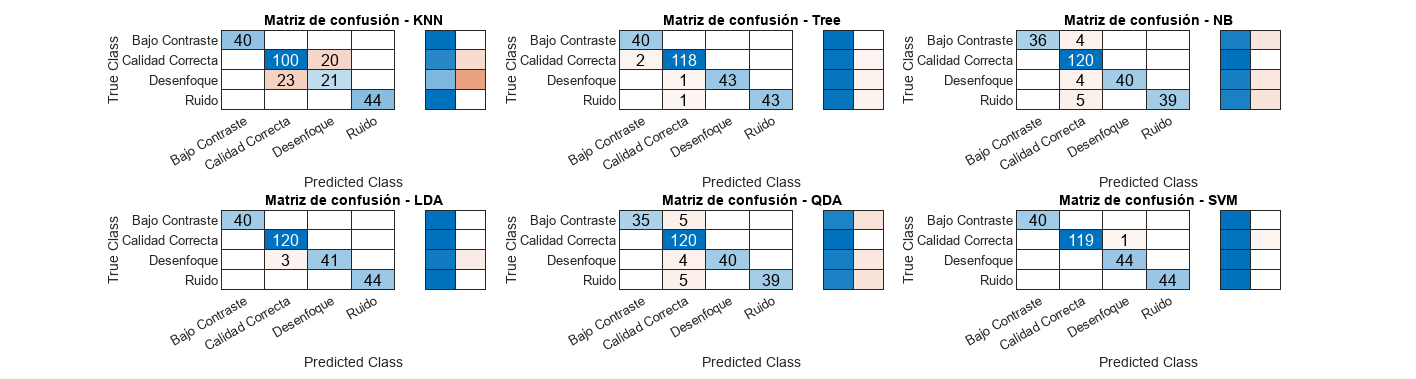

mdl_svm = fitcecoc(T_train, 'quality','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

Y_test  = T.quality(cv_out.training);
confMat = confusionmat(Y_test, Y_pred);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy);

subplot(2,3,6); confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized'); title('Matriz de confusión - SVM');

results = [results; table("SVM", mdl_loss, accuracy, Balanced_Accuracy,'VariableNames',{'model','loss','accuracy', 'balanced accuracy'})];

### Comparación de los distintos modelos

results

results = 6×4 table
        model          loss       accuracy    balanced accuracy
    _____________    _________    ________    _________________

    "knn"              0.17339    0.82661          0.87911     
    "tree"            0.016129    0.98387          0.98907     
    "naive_bayes"            0    0.94758          0.94924     
    "LDA"             0.012097     0.9879          0.98855     
    "QDA"            0.0044843    0.94355          0.94513     
    "SVM"            0.0040323    0.99597          0.99835     


[~, best_model] = max(results.accuracy);
results(best_model, :) 

ans = 1×4 table
    model      loss       accuracy    balanced accuracy
    _____    _________    ________    _________________

    "SVM"    0.0040323    0.99597          0.99835     


### Testeo del modelo final

#### **Support Vector Machines (SVM)**

mdl_final_SVM = fitcecoc(T_train, 'quality');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)

loss_final2 = 0.0161

accuracy_final2 = sum(strcmp(Y_pred2, T_test.quality)) / height(T_test.quality)

accuracy_final2 = 0.9836

Y_test  = T.quality(cv_out.test);
confMat = confusionmat(Y_test, Y_pred2);
numClasses = size(confMat, 1);
sensitivity = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);
for i = 1:numClasses
    TP = confMat(i, i); % Verdaderos Positivos
    FN = sum(confMat(i, :)) - TP; % Falsos Negativos
    TN = sum(diag(confMat)) - TP; % Verdaderos Negativos (suma de los TP de las clases distintas de i)
    FP = sum(confMat(:, i)) - TP; % Falsos Positivos
    
    sensitivity(i) = TP / (TP + FN); % Sensibilidad
    specificity(i) = TN / (TN + FP); % Especificidad
end

% Calcular la precisión balanceada
Balanced_Accuracy = (sensitivity + specificity) / 2;
Balanced_Accuracy = mean(Balanced_Accuracy)

Balanced_Accuracy = 0.9847

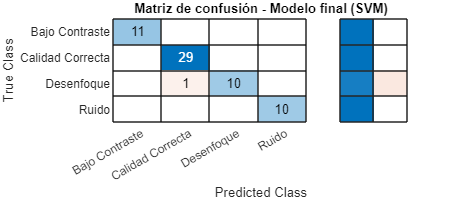

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('Matriz de confusión - Modelo final (SVM)')

## Guardar el modelo final

save('modelo_calidad_final_SVM.mat', 'mdl_final_SVM');

## Caracteristicas de imagenes no revisadas

### Extraer caracteristicas 

Extraer las caracteristicas de las imagenes no revisadas para predecir su calidad

% T_norevisada = T_metadata;
% T_norevisada = T_norevisada(T_norevisada.quality == 0, :);
% 
% [n, m] = size(T_norevisada);
% 
% entropia = zeros(n,1);
% rango_dinamico= zeros(n, 1);
% var_intensidad= zeros(n, 1);
% mse_mediana = zeros(n, 1);
% snr_mediana = zeros(n,1);
% 
% for i = 1:n
%     I = imread(T_norevisada.image{i});
%     entropia(i) = entropy(I);
% 
%     I = double(rgb2gray(I)); 
% 
%     rango_dinamico(i)=max(I(:))-min(I(:));
%     var_intensidad(i) =var(I(:));
% 
%     I_filtrada=medfilt2(I);
%     mse_mediana(i)=immse(I_filtrada, I);
%     snr_mediana(i)=psnr(I_filtrada, I);
% end
% 
% T_caracteristicas = table(T_norevisada.quality, entropia, rango_dinamico, var_intensidad, mse_mediana, snr_mediana, 'VariableNames', {'quality', 'entropia', 'rango_dinamico', 'var_intensidad', 'mse_mediana', 'snr_mediana'});
% 
% T_caracteristicas.imagen = T_norevisada.image;
% writetable(T_caracteristicas, 'CaracteristicasCalidadNOREVISADAS.csv');

## Predicción

T_metadata = readtable('metadata.csv');
no_revisadas = T_metadata.image(T_metadata.quality == 0);
T_caracteristicas_norevisadas = readtable("CaracteristicasCalidadNOREVISADAS.csv");

#### **Support Vector Machines (SVM)**

prediccion4 = predict(mdl_final_TODO_SVM, T_caracteristicas_norevisadas);
T_calidad4 = table(no_revisadas, prediccion4, 'VariableNames', {'Imagen', 'Calidad'});
Bajo_contraste_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Bajo Contraste'));
Calidad_correcta_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Calidad Correcta'));
Ruido_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Ruido'));
Desenfoque_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Desenfoque'));

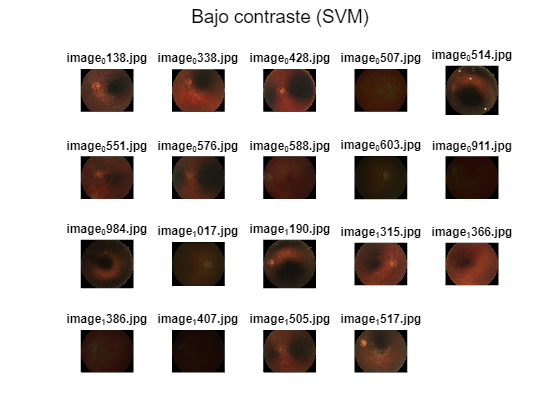

figure; sgtitle('Bajo contraste (SVM)')
for i=1:19
   subplot(4,5,i); imshow(Bajo_contraste_SVM{i}); title(Bajo_contraste_SVM{i})
end

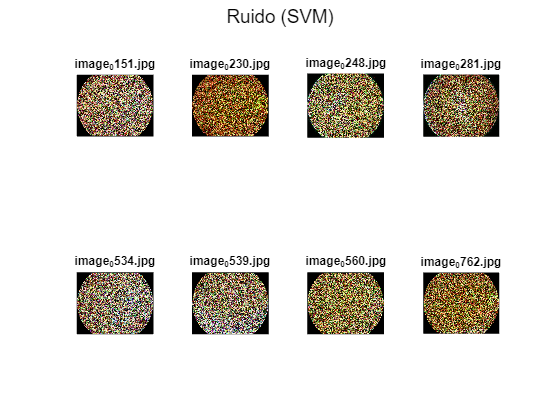

figure; sgtitle('Ruido (SVM)')
for i=1:8
   subplot(2,4,i); imshow(Ruido_SVM{i});title(Ruido_SVM{i})
end

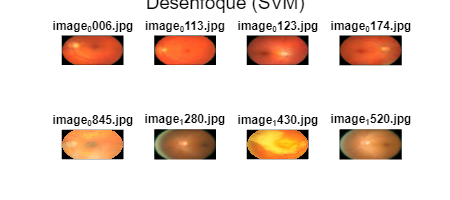

figure; sgtitle('Desenfoque (SVM)')
for i=1:8
   subplot(2,4,i); imshow(Desenfoque_SVM{i}); title(Desenfoque_SVM{i})
end

*Guradar las imagenes de buena calidad*

% carpeta_calidad_correcta = 'imagenes_calidad_correcta_SVM';
% mkdir(carpeta_calidad_correcta);
% 
% % Iterar sobre las imágenes y guardarlas en la carpeta
% for i = 1:numel(Calidad_correcta_SVM)
%     % Obtener el nombre de la imagen
%     nombre_imagen = Calidad_correcta_SVM{i};
%     
%     % Leer la imagen desde su ubicación original (o donde sea que estén almacenadas)
%     imagen = imread(nombre_imagen);
%     
%     % Guardar la imagen en la carpeta
%     [~, nombre_sin_extension, extension] = fileparts(nombre_imagen);
%     nombre_imagen_guardada = fullfile(carpeta_calidad_correcta, [nombre_sin_extension, extension]);
%     imwrite(imagen, nombre_imagen_guardada);
% end

## Imagenes calidad correcta

T_metadata = readtable('metadata.csv');
I_calidadcorrecta = [T_metadata.image(T_metadata.quality == 4, :); Calidad_correcta_SVM];

T_calidadcorrecta = T_metadata(ismember(T_metadata.image, I_calidadcorrecta), :);

writetable(T_calidadcorrecta, 'metadataCALIDADCORRECTA.csv');